## Figure 2

**Requirements: **thresholdfun.m, parameters.m all need to be in the working directory so that this script can call them

**Run Time:** 5 Minutes

clear;

%Make Parameters Global so that a range of DEs can be considered
global a;
global i;

%Mesh a & create storage for steady states
a = linspace(.02, .03,100);
ss = zeros(4,100);

%Create Mesh for initial guesses that are bounded within [0,1.5]
x0s = linspace(0,1.5,1000);

%For Each Model
for i = 1: length(a)
    
    %Zeros Storage
    zs = zeros(1000,1);
    
    %Try Newtons on each of our x0s. 
    for j = 1: length(zs)
        
        zs(j) = fzero(@DE, x0s(j));
    end
    
    %Store unique Zeros
    zs = uniquetol(zs,.001);
    
    %Snap Approximations of 0 to 0. Determining what was and wasn't a 
    %steady state at x = 0 was done by bounding the distance between 
    %the steady state values.
    for j = 1: length(zs)
        
        %If any of our steady states are actually an approximation to 0,
        %snap that value to 0
        if(zs(j) < 0 && zs(j) > -.15)
            zs(j) = 0;
        end
    end
    
    %Store Steady State Values
    for j = 1: length(zs)        
        ss(j,i) = zs(j);
    end
    
end

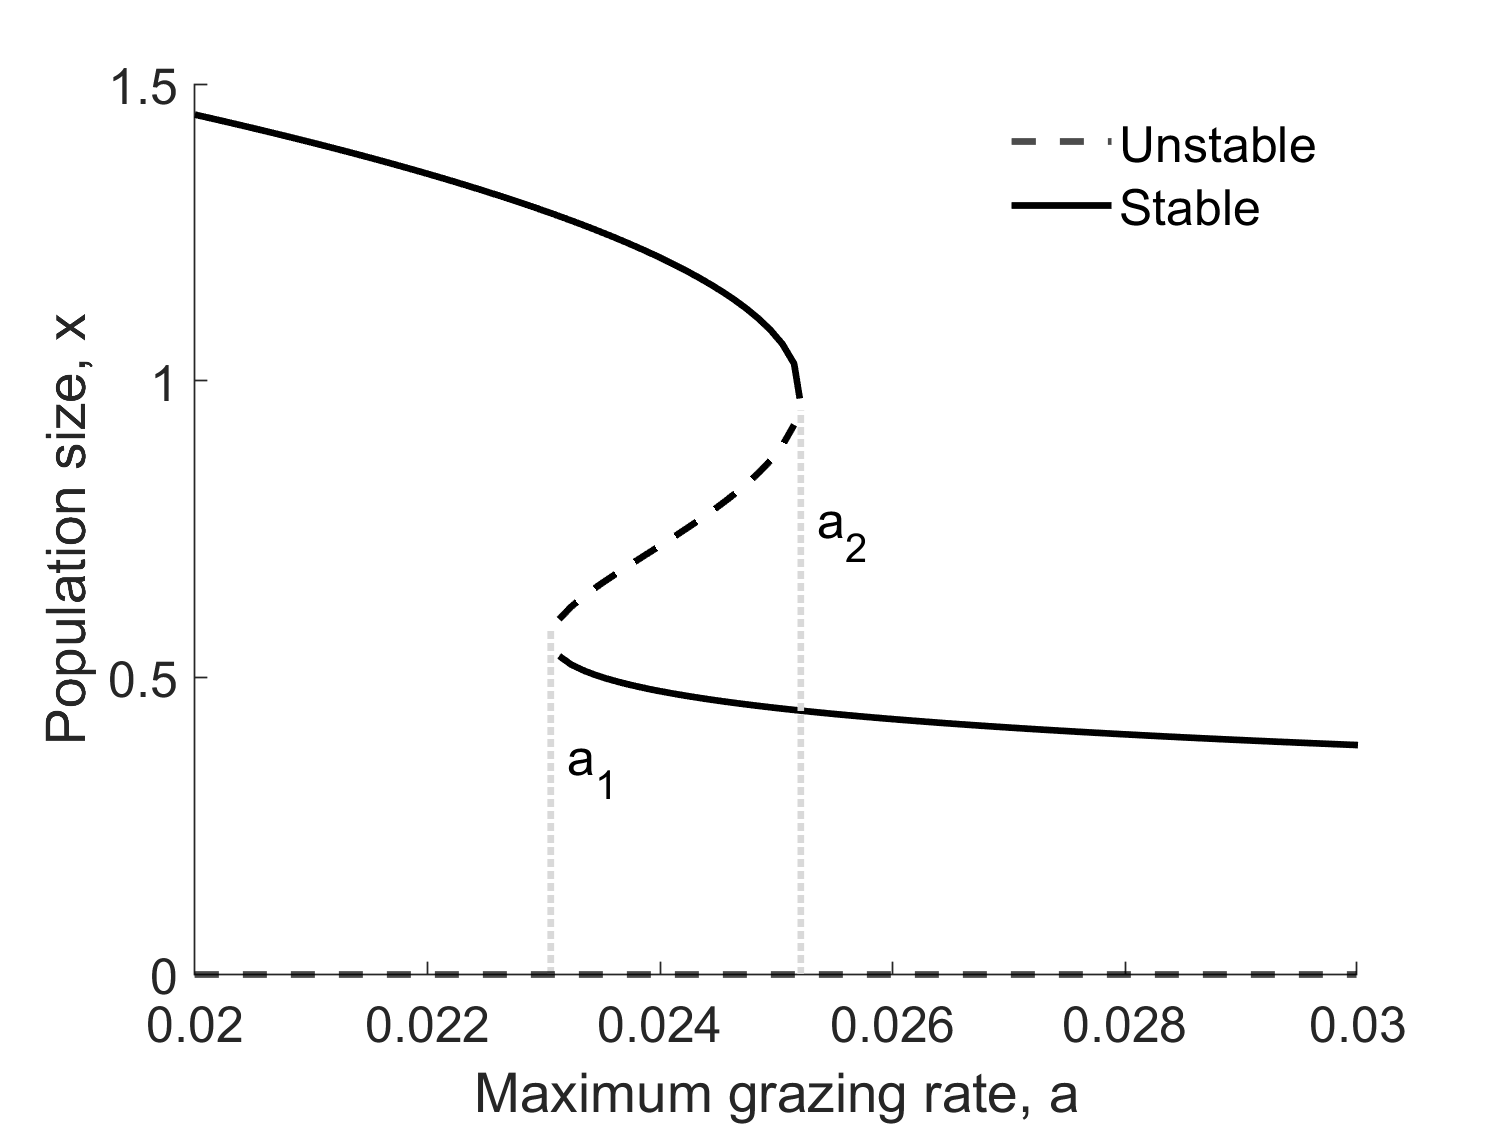

%Plotting

%Sort For Plotting Purposes
for i = length(ss)
    ss(:,i) = sort(ss(:,i));
end

%There Exists an unstable steady state across 0. 
figure;
yline(0,'k--','LineWidth',2);
hold on;

%First Solid Blue Line + a Joint Fix Between Data
p1 = [ss(2,1:31) ss(4,32:52)];
p1 = [p1 .97];
a1 = [a(1:52) .0252001];
plot(a1,p1,'k','LineWidth',2);

%Plot Unstable States
plot(a(32:52), ss(3,32:52),'k--','LineWidth',2);

%Plot rest of solid line
plot(a(32:52),ss(2,32:52),'k','LineWidth',2);
p4 = [ss(2,52:end-1) ss(4,end)];
plot(a(52:end),p4,'k','LineWidth',2);

%Draw a hat and a tilde
gry = 0.85;
line([.0230588 0.0230588], [0 .58], 'color', [gry gry gry],'linewidth',2,'linestyle',':');
line([0.0252092 0.0252092], [0 .95], 'color',[gry gry gry],'linewidth',2,'linestyle',':');

%Make Fig Pretty
xlabel('Maximum grazing rate, a',"FontSize",20);
ylabel('Population size, x',"FontSize",20);
legend('Unstable','Stable',"FontSize",15,'Location', 'best', 'Box', 'off');
set(gca,'FontSize',15);
text(.0232,.35,{'a_1'},"FontSize",15);
text(.02535,.75,{'a_2'},"FontSize",15);

% Prepare and save figure for publication
width = 600; % Width in pixels
height = 450; % Height in pixels
set(gcf, 'Position', [100, 100, width, height]); % Set figure position and size
exportgraphics(gcf, 'Fig2_withoutannotation.pdf', 'BackgroundColor', 'none');


% %Added ghost symbol (ghost.png0 and text "vegetation dominated" and "herbivore
% dominated" after, in Adobe Acrobat

**Our Differential Equation**

function f = DE(x)

global a;
global i;

%Parameters
[r,K,h,q,~] = parameters();

f = r * x * (1-(x/K)) - (a(i)*x^(q))/(x^(q) + h^(q));

end
